# Figure1: MF methods

## first, setup connctivity map

CurrentFolder = pwd

CurrentFolder = '/home/zx555/Documents/MATLAB/NYU-Vision-main/MFModel Code'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])

N_HC = 3; 
% Number of E and I neurons
n_E_HC = 54; n_I_HC = 31; % per side of HC
N_E = n_E_HC^2 * N_HC^2; % neuron numbers In all
N_I = n_I_HC^2 * N_HC^2;
% Grid sizes of E and I neurons; 
Size_HC = 0.500; % in mm;
Size_E = Size_HC/n_E_HC; Size_I = Size_HC/n_I_HC; 
% Projection: SD of distances
SD_E = 0.2/sqrt(2); SD_I = 0.125/sqrt(2);
Dist_LB = 0.36; % ignore the connection probability of dist>0.3mm
% Peak probability of projection
Peak_EE = 0.15; Peak_I = 0.6; 

% spatial indexes of E and I neurons
[NnE.X,NnE.Y] = V1Field_Generation(N_HC,1:N_E,'e');
[NnI.X,NnI.Y] = V1Field_Generation(N_HC,1:N_I,'i');

% determine connections between E, I
% sparse metrices containing 0 or 1. 
% Row_i Column_j means neuron j projects to neuron i
% add periodic boundary
C_EE = ConnectionMat(N_E,NnE,Size_E,...
                     N_E,NnE,Size_E,...
                     Peak_EE,SD_E,Dist_LB,1);

Elapsed time is 11.897547 seconds.



C_EI = ConnectionMat(N_E,NnE,Size_E,...
                     N_I,NnI,Size_I,...
                     Peak_I,SD_I,Dist_LB,0);

Elapsed time is 4.569564 seconds.



C_IE = ConnectionMat(N_I,NnI,Size_I,...
                     N_E,NnE,Size_E,...
                     Peak_I,SD_E,Dist_LB,0);

Elapsed time is 4.206642 seconds.



C_II = ConnectionMat(N_I,NnI,Size_I,...
                     N_I,NnI,Size_I,...
                     Peak_I,SD_I,Dist_LB,1);

Elapsed time is 1.497584 seconds.


% mVEpre = mVE; mVIpre = mVI;
% f_EnI0 = MeanFieldEst_BkGd(C_EE,C_EI,C_IE,C_II,...
%                                    S_EE,S_EI,S_IE,S_II,p_EEFail,...
%                                    lambda_E,S_Elgn,rE_amb,S_amb,...
%                                    lambda_I,S_Ilgn,rI_amb,...
%                                    gL_E,gL_I,Ve,Vi,mVE,mVI);


## Variables and Parameters

%RefTimeE = zeros(N_E,1); VE = 0.5*rand(N_E,1)-0.5; SpE = sparse(N_E,1); GE_ampa_R = zeros(N_E,1); GE_nmda_R = zeros(N_E,1); GE_gaba_R = zeros(N_E,1); GE_ampa_D = zeros(N_E,1); GE_nmda_D = zeros(N_E,1); GE_gaba_D = zeros(N_E,1);
%RefTimeI = zeros(N_I,1); VI = 1.5*rand(N_I,1)-0.5; SpI = sparse(N_I,1); GI_ampa_R = zeros(N_I,1); GI_nmda_R = zeros(N_I,1); GI_gaba_R = zeros(N_I,1); GI_ampa_D = zeros(N_I,1); GI_nmda_D = zeros(N_I,1); GI_gaba_D = zeros(N_I,1); 
load('Initials.mat')
%parameters
S_EEtest = [0.020 0.024 0.028]; 
S_IItest = [0.06  0.09  0.12  0.15  0.18];
S_EE = S_EEtest(2);
S_II = S_IItest(3);
p_EEFail = 0.2; S_amb = 0.01;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms
%dt = 0.2;
gL_E = 1/20;  Ve = 14/3;  rhoE_ampa = 0.8; rhoE_nmda = 0.2; %S_Elgn = 2*S_EE;
gL_I = 1/15;  Vi = -2/3;  rhoI_ampa = 0.67;rhoI_nmda = 0.33;

lambda_E = 0.08; lambda_I = 0.08;% ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period.
%rE_amb = 0.72; rI_amb = 0.36;
rE_amb = 0.50;   rI_amb = 0.50;

S_Elgntest = [1.5 2 2.5 3.0]*S_EE;
S_Elgn = S_Elgntest(3);
S_Ilgntest = [1   1.5 2 2.5]*S_Elgn;
S_Ilgn = S_Ilgntest(3);

%L6 input S_IEOneTime = 0.20*S_II;
S_EL6 = 1/3*S_EE; % S_IL6 = 1/3*S_IEOneTime; Now S_IL6 is porp to S_IE
rE_L6 = 0.25; % rI_L6 to be determined
rI_L6test  = [1:5,4.5]*rE_L6;
rI_L6 = rI_L6test(3);

% Replace S_EI by testing values
GridNum1 = 160; %160
GridNum2 = 160; %160
S_EI_Mtp = [0.8, 2.2]; % of S_EE
S_IE_Mtp = [0.1, 0.27]; % of S_II
S_EItest = linspace(S_EI_Mtp(1),S_EI_Mtp(2),GridNum1)*S_EE;
S_IEtest = linspace(S_IE_Mtp(1),S_IE_Mtp(2),GridNum2)*S_II;%*S_EE; I only specify a vecter length here

S_IL6test = 1/3 * S_IEtest;

## a. Select a (SIE, SEI) For all mV we concern, get corresponding firing rates

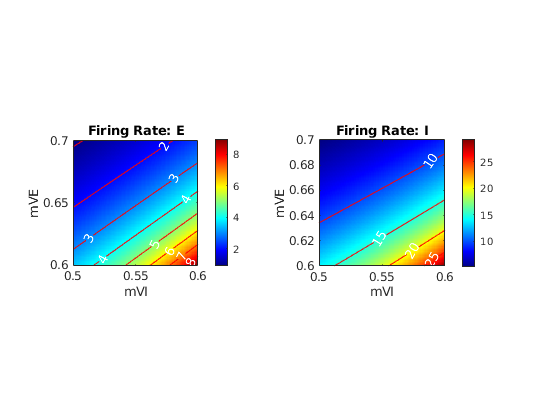

S_EI = 1.8*S_EE;
S_IE = 0.15*S_II;
S_IL6 = 1/3*S_IE;

mVEtest = 0.50:0.001:0.60;
mVItest = 0.60:0.001:0.70;
f_E_MF = zeros(length(mVEtest),length(mVItest));
f_I_MF = zeros(length(mVEtest),length(mVItest));
% collect neuron ind and connectivity for the center HC
E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);

I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2)); 
N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2));

% Mean-Field
for mVEInd = 1:length(mVEtest)
    mVE = mVEtest(mVEInd);
    for mVIInd = 1:length(mVItest)
        mVI = mVItest(mVIInd);
        f_EnI_Now  = MeanFieldEst_BkGd_L6_OneStep(N_EE,N_EI,N_IE,N_II,...
                                   S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                   lambda_E,S_Elgn,rE_amb,S_amb,...
                                   lambda_I,S_Ilgn,rI_amb,...
                                   S_EL6,S_IL6,rE_L6,rI_L6,...
                                   gL_E,gL_I,Ve,Vi,mVE,mVI);
        f_E_MF(mVEInd,mVIInd) = f_EnI_Now(1);
        f_I_MF(mVEInd,mVIInd) = f_EnI_Now(2);
    end                                                         
end

figure(2)
subplot 121
imagesc(mVEtest,mVItest,f_E_MF)
xlabel('mVI'); ylabel('mVE');
set(gca,'YDir','Normal')
colorbar
axis square
hold on
[C1,h1]= contour(mVEtest,mVItest,f_E_MF,'ShowText','on','color','r');
clabel(C1,h1,'FontSize',10,'Color','k')
axis square
hold off
axis([ min(mVEtest) max(mVEtest) min(mVItest) max(mVItest)])
title('Firing Rate: E')

subplot 122
imagesc(mVEtest,mVItest,f_I_MF)
xlabel('mVI'); ylabel('mVE');
set(gca,'YDir','Normal')
colorbar
axis square
hold on
[C2,h2]= contour(mVEtest,mVItest,f_I_MF,'ShowText','on','color','r');
clabel(C2,h2,'FontSize',10,'Color','k')
axis square
hold off
axis([min(mVEtest) max(mVEtest) min(mVItest) max(mVItest) ])
title('Firing Rate: I')
colormap jet

## b1. Firing rate curve: Real and MF est

S_IE = 0.15*S_II; S_IL6 = 1/3*S_IE;
S_EItest = linspace(1.45,1.9,15)*S_EE;

cluster = gcp('nocreate');
if isempty(cluster)
    cluster = parpool([4 64]);
    cluster.IdleTimeout = 1200;
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).



Fr_NoFix_ref = zeros(2,length(S_EItest));
mV_NoFix_ref = zeros(2,length(S_EItest));
Fr_NoFixVar_ref = zeros(2,length(S_EItest));
mV_NoFixVar_ref = zeros(2,length(S_EItest));
Fr_NoFixTraj_ref = cell(length(S_EItest),1);
mV_NoFixTraj_ref = cell(length(S_EItest),1);

loopCount_ref = zeros(1,length(S_EItest)); % count the number of loops
ConvIndi_ref = logical(loopCount_ref);
failureInd = logical(loopCount_ref);
SampleNum = 400;
MaxNum = 500;
h = 1;
SimuT = 40*1e3;
tic
parfor S_EIInd = 1:length(S_EItest)
    S_EI = S_EItest(S_EIInd);
    tic
    [Fr_NoFixTraj_ref{S_EIInd},mV_NoFixTraj_ref{S_EIInd},loopCount_ref(S_EIInd),ConvIndi_ref(S_EIInd),failureInd(S_EIInd)]...
                  = MeanFieldEst_BkGd_Indep_StepSize_ref_testL6(C_EE,C_EI,C_IE,C_II,...
                                            S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                            lambda_E,S_Elgn,rE_amb,S_amb,...
                                            lambda_I,S_Ilgn,rI_amb,...
                                            S_EL6,S_IL6,rE_L6,rI_L6,...
                                            tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
                                            rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                            gL_E,gL_I,Ve,Vi,...
                                            N_HC,n_E_HC,n_I_HC,'End',SampleNum,MaxNum,h,SimuT);
                                        
    toc
end

Elapsed time is 45.928583 seconds.
Elapsed time is 47.246856 seconds.
Elapsed time is 48.769410 seconds.
Elapsed time is 50.470052 seconds.
Elapsed time is 50.594655 seconds.
Elapsed time is 53.626630 seconds.
Elapsed time is 40.811228 seconds.
Elapsed time is 42.222473 seconds.
Elapsed time is 38.922195 seconds.
Elapsed time is 41.108752 seconds.
Elapsed time is 38.863000 seconds.
Elapsed time is 43.020909 seconds.
Elapsed time is 27.913104 seconds.
Elapsed time is 28.683752 seconds.
Elapsed time is 28.000798 seconds.


toc

Elapsed time is 124.109329 seconds.



for S_EIInd = 1:length(S_EItest)
    Fr_NoFix_ref(:,S_EIInd) = mean(Fr_NoFixTraj_ref{S_EIInd}(:,end-SampleNum:end),2);
    mV_NoFix_ref(:,S_EIInd) = mean(mV_NoFixTraj_ref{S_EIInd}(:,end-SampleNum:end),2);
    Fr_NoFixVar_ref(:,S_EIInd) = var(Fr_NoFixTraj_ref{S_EIInd}(:,end-SampleNum:end),0,2);
    mV_NoFixVar_ref(:,S_EIInd) = var(mV_NoFixTraj_ref{S_EIInd}(:,end-SampleNum:end),0,2);
end

## b2. Network Simulation

S_EE = 0.024, S_EI = 0.0456, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

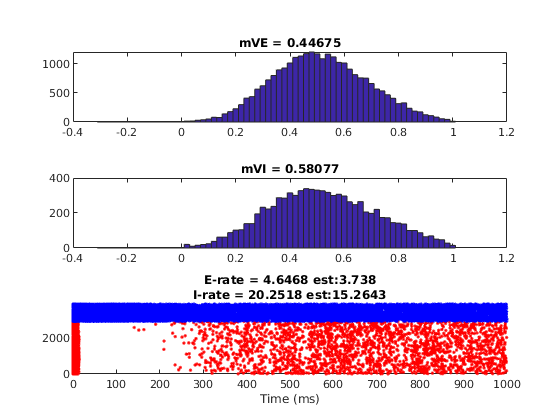

S_EE = 0.024, S_EI = 0.0456, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.0456, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.044829, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.044829, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.044829, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

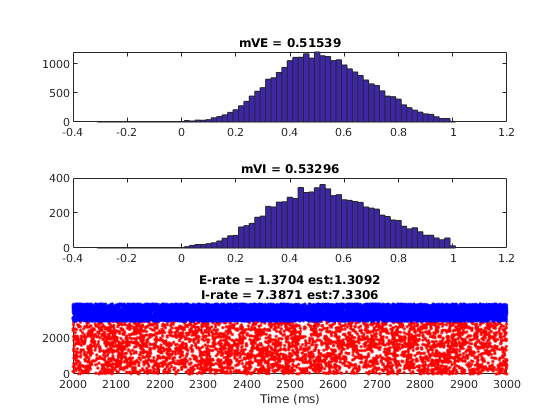

S_EE = 0.024, S_EI = 0.044057, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

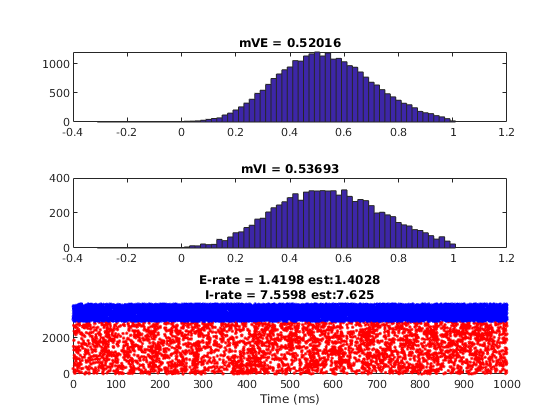

S_EE = 0.024, S_EI = 0.044057, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.044057, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.043286, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.043286, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

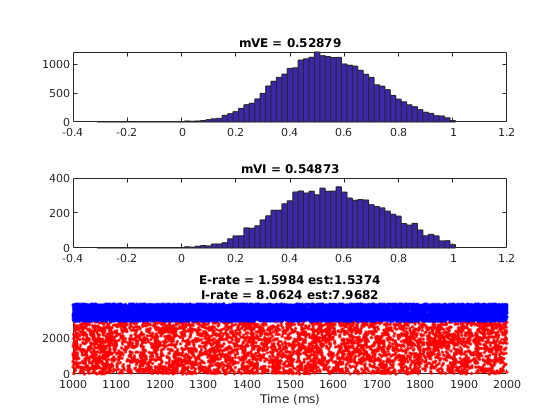

S_EE = 0.024, S_EI = 0.043286, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

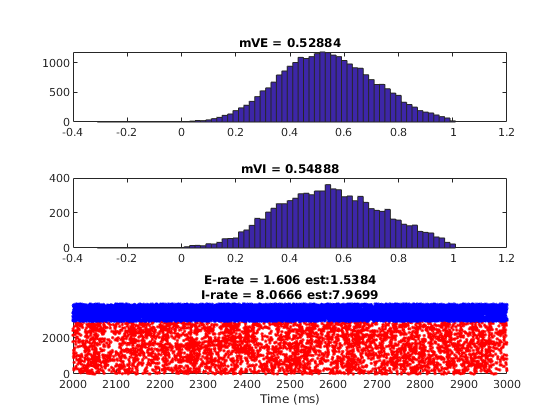

S_EE = 0.024, S_EI = 0.042514, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.042514, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.042514, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

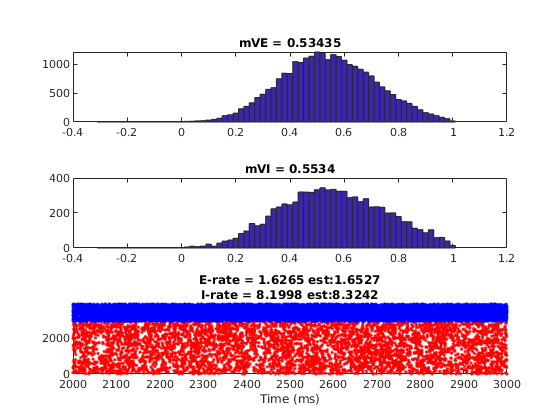

S_EE = 0.024, S_EI = 0.041743, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

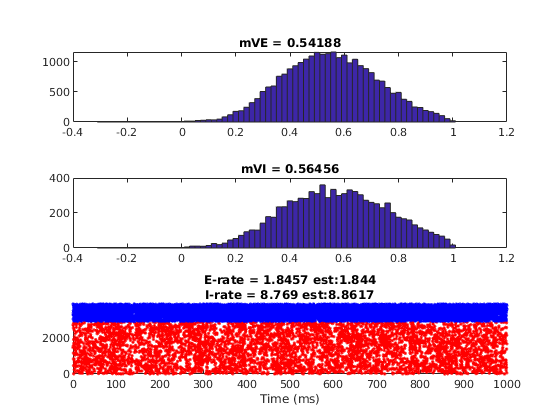

S_EE = 0.024, S_EI = 0.041743, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

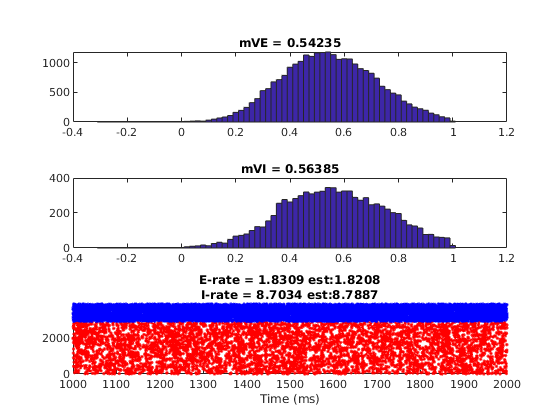

S_EE = 0.024, S_EI = 0.041743, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

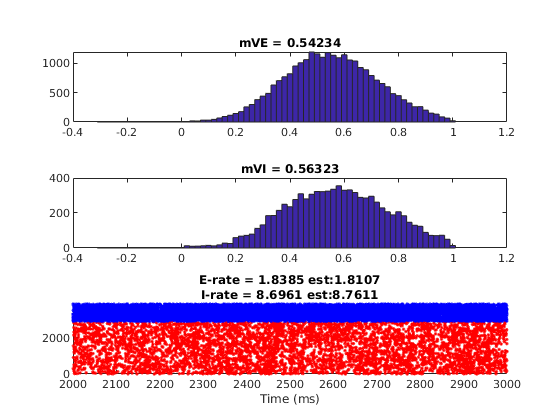

S_EE = 0.024, S_EI = 0.040971, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

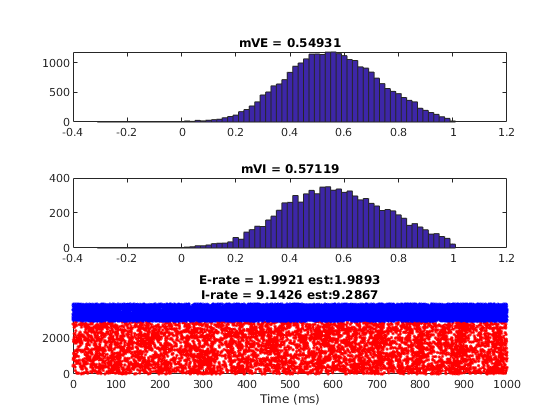

S_EE = 0.024, S_EI = 0.040971, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

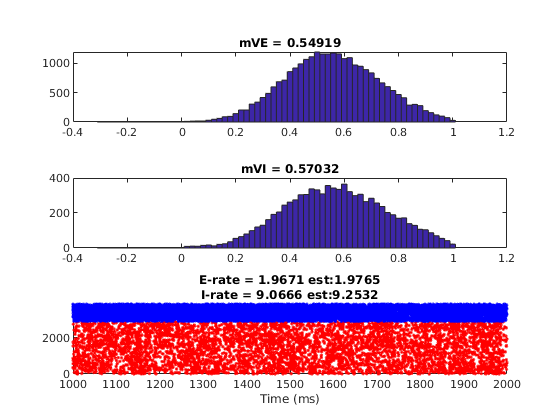

S_EE = 0.024, S_EI = 0.040971, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.0402, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.0402, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.0402, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.039429, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

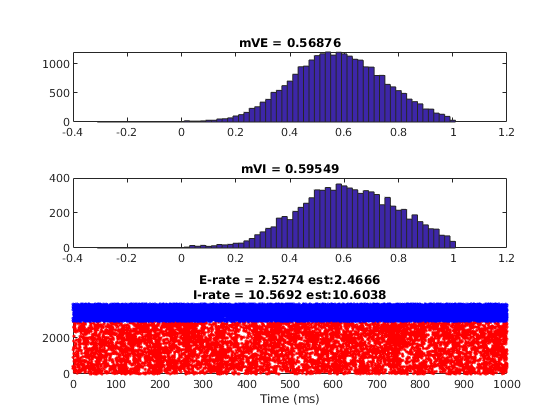

S_EE = 0.024, S_EI = 0.039429, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

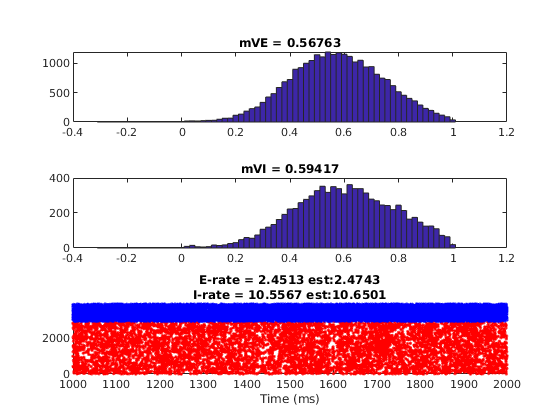

S_EE = 0.024, S_EI = 0.039429, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

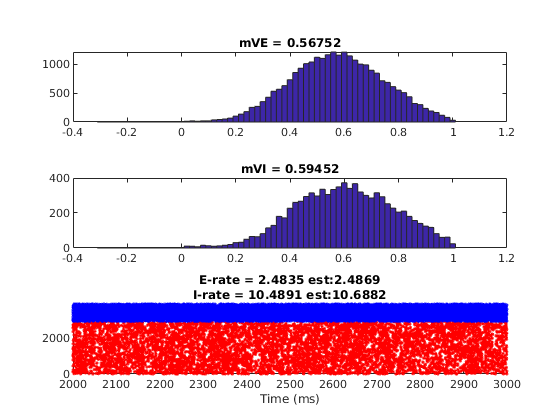

S_EE = 0.024, S_EI = 0.038657, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.038657, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.038657, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.037886, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.037886, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.037886, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.037114, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.037114, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.037114, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.036343, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.036343, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

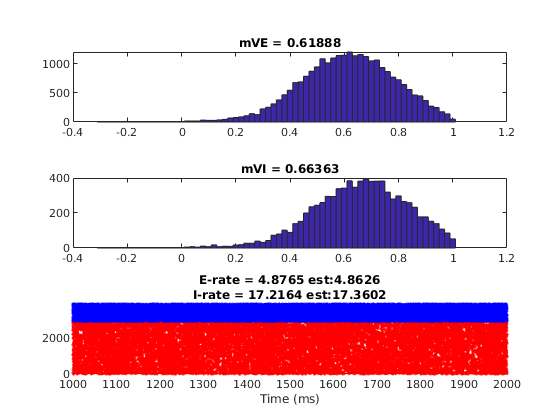

S_EE = 0.024, S_EI = 0.036343, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

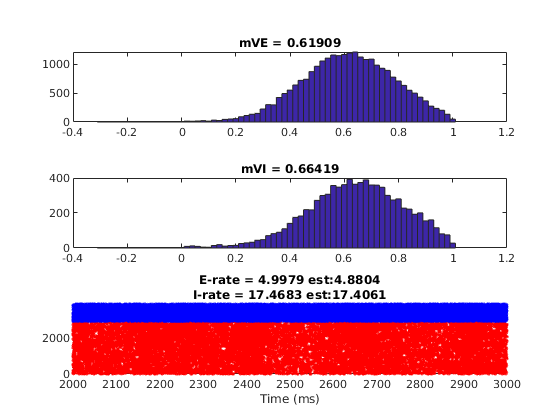

S_EE = 0.024, S_EI = 0.035571, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.035571, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

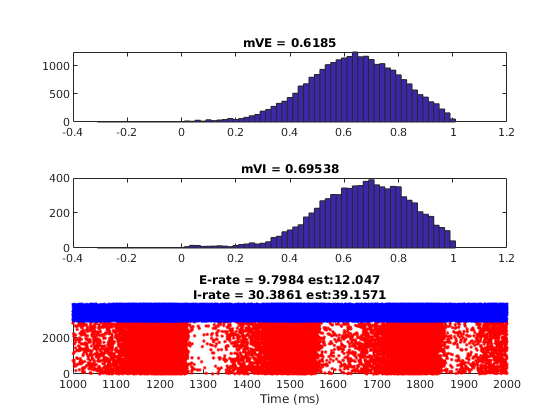

S_EE = 0.024, S_EI = 0.035571, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.06, lambda_E = 0.08, S_Ilgn = 0.12, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

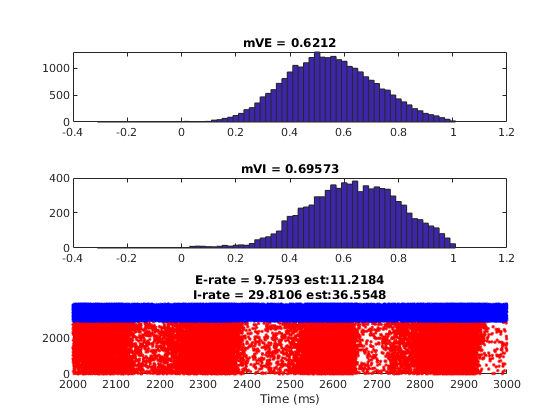

T = 3000;  SimulationT = 1000; dt = 0.1;%sampleT = 2;
% E-to-E delay time
T_EEDly = 1; N_EEDly = floor(T_EEDly/dt);

Fr_NW = zeros(2,length(S_EItest));
mV_NW = zeros(2,length(S_EItest));
Fr_OneStep = zeros(2,length(S_EItest)); % one step MF estimation using network mV

Fr_NWTraj = cell(1,length(S_EItest)); % tracing network firing rate 
FrWinSize = 200; FrWinStep = 50;
FrWinNum = floor((T-FrWinSize)/FrWinStep) + 1;

E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
    
I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2)); 
N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2));

EEDlyRcd = sparse(N_E,N_EEDly);
for S_EIInd = length(S_EItest):-1:1
    S_EI = S_EItest(S_EIInd);
    %E_SpHis= []; I_SpHis=[];
    E_Sp = []; I_Sp = [];
    VE_T = []; VI_T = [];
    %sampleN = floor(sampleT/dt); % sample each 2 ms
    SimulationN = floor(SimulationT/dt); % show and check every 200ms
    for TimeN = 1:floor(T/dt)
    [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,...
                        oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
     oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
                        oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
                        oEEDlyRcd] = ...
          V1NetworkUpdate_Ver2_EEDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,...
                                          GE_ampa_D,GE_nmda_D,GE_gaba_D,...
                          RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
                                          GI_ampa_D,GI_nmda_D,GI_gaba_D,...
                                          EEDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
                          C_EE,C_EI,C_IE,C_II,...
                          S_EE,S_EI,S_IE,S_II,...
                          tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
                          dt,p_EEFail,...
                          gL_E,Ve,S_Elgn,rhoE_ampa,rhoE_nmda,...
                          gL_I,Vi,S_Ilgn,rhoI_ampa,rhoI_nmda,...
                          S_amb,lambda_E,lambda_I,rE_amb,rI_amb,...
                          S_EL6,S_IL6,rE_L6,rI_L6);
                      
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
                                              GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
                                              GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd;
% When reaching every 200ms, demostrate and pause
    if mod(TimeN,SimulationN) == 0 && TimeN*dt>500
        ParameterDisp = ['S_EE = ' num2str(S_EE) ', S_EI = ' num2str(S_EI) ...
                         ', S_IE = ' num2str(S_IE) ', S_II = ' num2str(S_II) '\n' ...
                         'S_Elgn = ' num2str(S_Elgn) ', lambda_E = ' num2str(lambda_E) ...
                         ', S_Ilgn = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
                         'S_amb = ' num2str(S_amb) ', rE_amb = ' num2str(rE_amb) ', rI_amb = ' num2str(rI_amb)];
    
    fprintf(ParameterDisp)
    h = figure('Name','TestRaster');
    subplot 311
    hist(oVE,-0.3:0.02:1)
    title(['mVE = ' num2str(nanmean(VE_T))])
    %E_SpHis = [E_SpHis,sum(oSpE)];
    %axis([-0.4 1.1 0 6000])
    
    subplot 312
    hist(oVI,-0.3:0.02:1)
    title(['mVI = ' num2str(nanmean(VI_T))])
    %I_SpHis = [I_SpHis,sum(oSpI)];
    %axis([-0.4 1.1 0 2000])
    
    

    %E_Ind = 10000:13000; I_Ind = 3300:4300;
    scatterE = find(ismember(E_Sp(:,1),E_Ind));
    scatterI = find(ismember(I_Sp(:,1),I_Ind));
    [~,E_Fire_Ind] = ismember(E_Sp(scatterE,1),E_Ind);
    [~,I_Fire_Ind] = ismember(I_Sp(scatterI,1),I_Ind);

    WinSize = SimulationT;
    T_RateWindow = [TimeN*dt-WinSize TimeN*dt];
    E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
    I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
    E_Rate = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
    I_Rate = length(I_SpInd)/(WinSize/1000)/length(I_Ind);

    f_EnIOneStep = MeanFieldEst_BkGd_L6_OneStep(N_EE,N_EI,N_IE,N_II,...
                                   S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                   lambda_E,S_Elgn,rE_amb,S_amb,...
                                   lambda_I,S_Ilgn,rI_amb,...
                                   S_EL6,S_IL6,rE_L6,rI_L6,...
                                   gL_E,gL_I,Ve,Vi,nanmean(VE_T),nanmean(VI_T));

    subplot 313
    hold on
    scatter(E_Sp(scatterE,2),E_Fire_Ind,'r.')
    scatter(I_Sp(scatterI,2),I_Fire_Ind+max(E_Fire_Ind),'b.');
    title({['E-rate = ' num2str(E_Rate) ' est:' num2str(f_EnIOneStep(1))],['I-rate = ' num2str(I_Rate) ' est:' num2str(f_EnIOneStep(2))]})
    xlabel('Time (ms)')
    xlim(T_RateWindow)
    ylim([0 max(I_Fire_Ind)+max(E_Fire_Ind)])
    drawnow
    %pause
    close(h)
    end

    E_Sp = [E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]];
    I_Sp = [I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]];
    VE_T = [VE_T;nanmean(oVE(E_Ind))];
    VI_T = [VI_T;nanmean(oVI(I_Ind))];
    if sum(isnan(oVE))>0.8*N_E
        error('warning!: Network exploded')
    end
    end
    Fr_NW(:,S_EIInd) = [E_Rate;I_Rate];
    mV_NW(:,S_EIInd) = [nanmean(VE_T),nanmean(VI_T)];
    Fr_OneStep(:,S_EIInd) = f_EnIOneStep;
    
    % Trace firing rates of neurons concerns
    Fr_NWtrace = zeros(2,FrWinNum);
    for Fr_winInd = 1:FrWinNum
        RateWindow = [(Fr_winInd-1)*FrWinStep, (Fr_winInd-1)*FrWinStep+FrWinSize];
        E_SpInd = find(E_Sp(:,2)>=RateWindow(1) & E_Sp(:,2)<=RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=RateWindow(1) & I_Sp(:,2)<=RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        Fr_NWtrace(1,Fr_winInd) = length(E_SpInd)/(FrWinSize/1000)/length(E_Ind);
        Fr_NWtrace(2,Fr_winInd) = length(I_SpInd)/(FrWinSize/1000)/length(I_Ind);
    end
    Fr_NWTraj{S_EIInd} = Fr_NWtrace;
end

## b3. Figure Plot

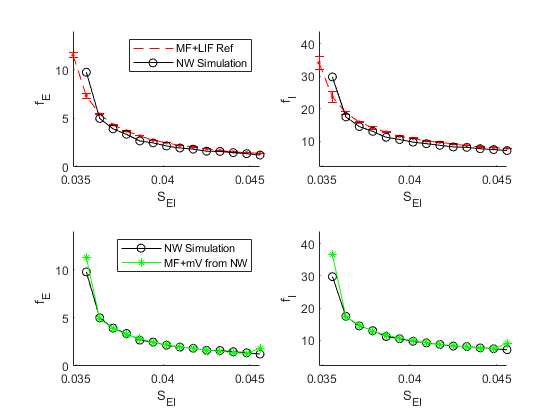

Fr_NW(Fr_NW == 0) = nan;
Fr_OneStep(Fr_OneStep == 0) = nan;

figure('Name','MFEstimation VS Network Simulation')
subplot 221
hold on
%plot(S_EItest,Fr_Fix(1,:),'g')
%scatter(repmat(S_EItest',MFSampleN,1),reshape(squeeze(Fr_NoFix(1,:,1:MFSampleN)),...
%                                    length(S_EItest)*MFSampleN,1),'r.')
plot(S_EItest,Fr_NoFix_ref(1,:),'r--','DisplayName','MF+LIF Ref')
hebarE = errorbar(S_EItest,Fr_NoFix_ref(1,:),Fr_NoFixVar_ref(1,:),'r.');
set(get(get(hebarE,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
plot(S_EItest,Fr_NW(1,:),'k','Marker','o','DisplayName','NW Simulation')
xlabel('S_{EI}'); ylabel('f_E')
legend
xlim([min(S_EItest) max(S_EItest)])
ylim([0 14])
ParameterDisp = ['S_{EE} = ' num2str(S_EE) ...
                         ', S_{IE} = ' num2str(S_IE) ', S_{II} = ' num2str(S_II) '\n' ...
                         'S_{Elgn} = ' num2str(S_Elgn) ', lambda_E = ' num2str(lambda_E) '\n' ...
                         ', S_{Ilgn} = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
                         'S_{amb} = ' num2str(S_amb) ', rE_{amb} = ' num2str(rE_amb) ', rI_{amb} = ' num2str(rI_amb) '\n' ...
                         'S_{EL6} = ' num2str(S_EL6) ', S_{IL6} = ' num2str(S_IL6) 'r_{EL6} = ' num2str(rE_L6) ', r_{IL6} = ' num2str(rI_L6)  ];
titlePara = sprintf(ParameterDisp);
%title(titlePara)

subplot 222
hold on
% plot(S_EItest,Fr_Fix(2,:),'g')
% scatter(repmat(S_EItest',MFSampleN,1),reshape(squeeze(Fr_NoFix(2,:,1:MFSampleN)),...
%                                     length(S_EItest)*MFSampleN,1),'r.')
plot(S_EItest,Fr_NoFix_ref(2,:),'r--')
hebarI = errorbar(S_EItest,Fr_NoFix_ref(2,:),Fr_NoFixVar_ref(2,:),'r.');
set(get(get(hebarI,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
plot(S_EItest,Fr_NW(2,:),'k','Marker','o')
xlabel('S_{EI}'); ylabel('f_I')
xlim([min(S_EItest) max(S_EItest)])
ylim([2 44])

subplot 223
hold on
%plot(S_EItest,Fr_Fix(1,:),'g')
%scatter(repmat(S_EItest',MFSampleN,1),reshape(squeeze(Fr_NoFix(1,:,1:MFSampleN)),...
%                                    length(S_EItest)*MFSampleN,1),'r.')
set(get(get(hebarE,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
plot(S_EItest,Fr_NW(1,:),'k','Marker','o','DisplayName','NW Simulation')
plot(S_EItest,Fr_OneStep(1,:),'g','Marker','*','DisplayName','MF+mV from NW')
xlabel('S_{EI}'); ylabel('f_E')
legend
xlim([min(S_EItest) max(S_EItest)])
ylim([0 14])
ParameterDisp = ['S_{EE} = ' num2str(S_EE) ...
                         ', S_{IE} = ' num2str(S_IE) ', S_{II} = ' num2str(S_II) '\n' ...
                         'S_{Elgn} = ' num2str(S_Elgn) ', lambda_E = ' num2str(lambda_E) '\n' ...
                         ', S_{Ilgn} = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
                         'S_{amb} = ' num2str(S_amb) ', rE_{amb} = ' num2str(rE_amb) ', rI_{amb} = ' num2str(rI_amb) '\n' ...
                         'S_{EL6} = ' num2str(S_EL6) ', S_{IL6} = ' num2str(S_IL6) 'r_{EL6} = ' num2str(rE_L6) ', r_{IL6} = ' num2str(rI_L6)  ];
titlePara = sprintf(ParameterDisp);
%title(titlePara)

subplot 224
hold on
% plot(S_EItest,Fr_Fix(2,:),'g')
% scatter(repmat(S_EItest',MFSampleN,1),reshape(squeeze(Fr_NoFix(2,:,1:MFSampleN)),...
%                                     length(S_EItest)*MFSampleN,1),'r.')
set(get(get(hebarI,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
plot(S_EItest,Fr_NW(2,:),'k','Marker','o')
plot(S_EItest,Fr_OneStep(2,:),'g','Marker','*')
xlabel('S_{EI}'); ylabel('f_I')
xlim([min(S_EItest) max(S_EItest)])
ylim([2 44])


% subplot 413
% hold on
% % plot(S_EItest,mV_Fix(1,:),'g')
% % scatter(repmat(S_EItest',MFSampleN,1),reshape(squeeze(mV_NoFix(1,:,1:MFSampleN)),...
% %                                     length(S_EItest)*MFSampleN,1),'r.')
% plot(S_EItest,mV_NoFix_ref(1,:),'r--')
% errorbar(S_EItest,mV_NoFix_ref(1,:),mV_NoFixVar_ref(1,:),'r')
% plot(S_EItest,mV_NW(1,:),'k','Marker','o')
% xlabel('S_{EI}'); ylabel('mV_E')
% legend('MF+LIF Ref','var of MF','Network Simulation')
% xlim([min(S_EItest) max(S_EItest)])
% 
% subplot 414
% hold on
% % plot(S_EItest,mV_Fix(2,:),'g')
% % scatter(repmat(S_EItest',MFSampleN,1),reshape(squeeze(mV_NoFix(2,:,1:MFSampleN)),...
% %                                     length(S_EItest)*MFSampleN,1),'r.')
% plot(S_EItest,mV_NoFix_ref(2,:),'r--')
% errorbar(S_EItest,mV_NoFix_ref(2,:),mV_NoFixVar_ref(1,:),'r')
% plot(S_EItest,mV_NW(2,:),'k','Marker','o')
% xlabel('S_{EI}'); ylabel('mV_I')
% xlim([min(S_EItest) max(S_EItest)])

## C: MF Trajs

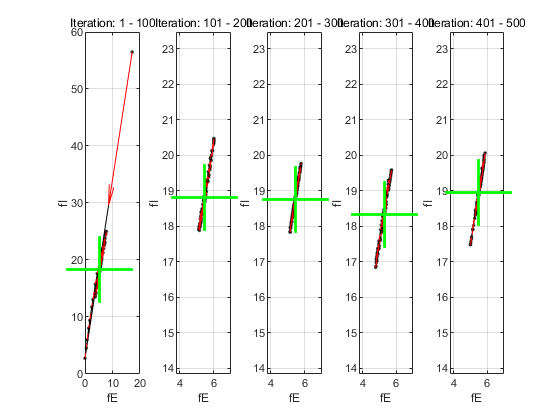

figure('Name','Trajectories')
TrajInd = 3;
IteraN = 100;
TrajC = Fr_NoFixTraj_ref{TrajInd};
for TrajPanInd = 1:5 

subplot(1,5,TrajPanInd)
plot_dir(TrajC(1, 1+(TrajPanInd-1)*IteraN : TrajPanInd*IteraN)',...
         TrajC(2, 1+(TrajPanInd-1)*IteraN : TrajPanInd*IteraN)');
hold on
plot(mean(TrajC(1, 1+(TrajPanInd-1)*IteraN : TrajPanInd*IteraN)), ...
     mean(TrajC(2, 1+(TrajPanInd-1)*IteraN : TrajPanInd*IteraN)),...
     'Marker','+','MarkerSize',50,'color','g','LineWidth',2)     
     
xlabel('fE');ylabel('fI')

title(sprintf('Iteration: %d - %d', 1+(TrajPanInd-1)*IteraN, TrajPanInd*IteraN))

if TrajPanInd>1
    axis([min(TrajC(1,IteraN:end))-1 max(TrajC(1,IteraN:end))+1 ...
          min(TrajC(2,IteraN:end))-3 max(TrajC(2,IteraN:end))+3])
end
end

## D: LIF Only Algorithm

% initialize with a reasonable guess
meanVs = [];
f_EnIpre = [0;0]; % start with an impossible value
N_Neuron = 40; % Number of Neurons we use
InitialStatesE = struct('v',zeros(1,N_Neuron),'G_gaba_D',zeros(1,N_Neuron),'G_gaba_R',zeros(1,N_Neuron),...
    'G_ampa_D',zeros(1,N_Neuron),'G_ampa_R',zeros(1,N_Neuron),...
    'G_nmda_D',zeros(1,N_Neuron),'G_nmda_R',zeros(1,N_Neuron));
InitialStatesI = struct('v',zeros(1,N_Neuron),'G_gaba_D',zeros(1,N_Neuron),'G_gaba_R',zeros(1,N_Neuron),...
    'G_ampa_D',zeros(1,N_Neuron),'G_ampa_R',zeros(1,N_Neuron),...
    'G_nmda_D',zeros(1,N_Neuron),'G_nmda_R',zeros(1,N_Neuron));


% Run Single Cell Simulation
f_EnI0 = [3.0;10];
f_EnIOut  = f_EnI0;
loop = 0;
tic
while loop<501 %%% relative difference for firing rates!!    
    mVEpre = mVE; mVIpre = mVI;
    f_EnINow = zeros(size(f_EnI0)); % from simulation
    
    % simulate multiple neurons
    [mVE,f_EnINow(1),EndStatesE] = MF_Free_LIFEst_MultiCell_L6('e', f_EnI0, ...
        N_EE,N_EI,N_IE,N_II,...
        S_EE,S_EI,S_IE,S_II,p_EEFail,...
        lambda_E,S_Elgn,rE_amb,S_amb,...
        lambda_I,S_Ilgn,rI_amb,...
        S_EL6,S_IL6,rE_L6,rI_L6,...
        tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
        rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
        gL_E,gL_I,Ve,Vi,InitialStatesE,N_Neuron);
    [mVI,f_EnINow(2),EndStatesI] = MF_Free_LIFEst_MultiCell_L6('i', f_EnI0, ...
        N_EE,N_EI,N_IE,N_II,...
        S_EE,S_EI,S_IE,S_II,p_EEFail,...
        lambda_E,S_Elgn,rE_amb,S_amb,...
        lambda_I,S_Ilgn,rI_amb,...
        S_EL6,S_IL6,rE_L6,rI_L6,...
        tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
        rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
        gL_E,gL_I,Ve,Vi,InitialStatesI,N_Neuron);
    
    loop = loop+1;
    %f_EnINow
    f_EnIpre = f_EnI0;
    f_EnI0 = (f_EnINow+f_EnIpre)/2; % Take last two average for the next one
    f_EnIOut = [f_EnIOut,f_EnINow];
    meanVs = [meanVs, [mVE;mVI]];
    
    InitialStatesE = EndStatesE; InitialStatesI = EndStatesI; % Now if forms a loop
end
toc

历时 298.361650 秒。



figure('Name','Trajectories: LIF only')
TrajD = f_EnIOut;
xlimit = [0 50];

ax1a = subplot(211);
hold on
plot(TrajC(1,:),'r-','DisplayName','MF+LIF')
xlim(xlimit)
ylabel('f_E')
%yyaxis right
plot(TrajD(1,:),'r-','Marker','o','DisplayName','LIF only')
xlim(xlimit)
legend

as21 = subplot(212)

as21 =   Axes - 属性:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.3412]
            Units: 'normalized'

  显示 所有属性


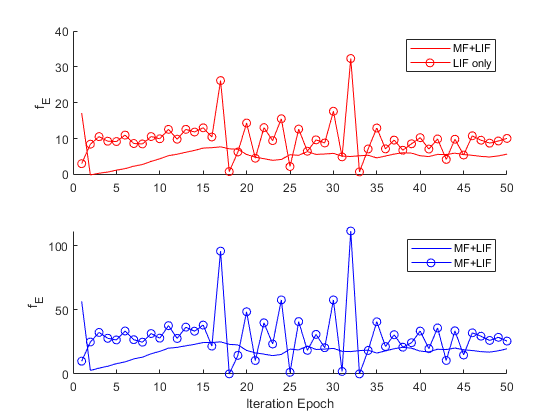

hold on
plot(TrajC(2,:),'b-','DisplayName','MF+LIF')
xlim(xlimit)
xlabel('Iteration Epoch')
ylabel('f_E')
%yyaxis right

plot(TrajD(2,:),'b-','Marker','o','DisplayName','LIF only')
xlim(xlimit)
legend

## F: Ref or not. We test different setup of tau_ref

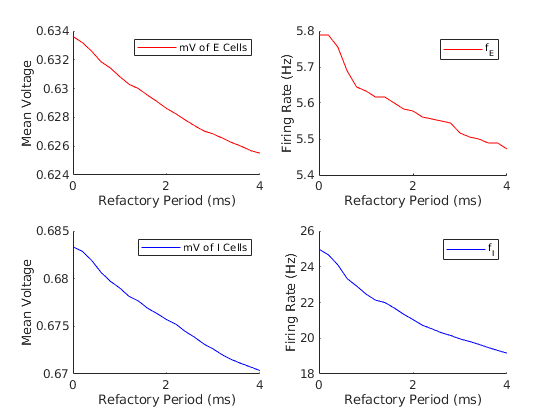

% ref period range
tau_ref_Test = 0:0.2:4;
% 
vTraj_refTest = cell(2,length(tau_ref_Test));
mV_refTest = zeros(2,length(tau_ref_Test));
mVstd_refTest = zeros(2,length(tau_ref_Test));
fr_refTest = zeros(2,length(tau_ref_Test));
% LIF parameters
LIFSimuT = 200*1e3;
S_EIInd = 3;
f_EnI_reftest = Fr_NoFix_ref(:,S_EIInd);
S_EI = S_EItest(S_EIInd);

for refTestInd = 1:length(tau_ref_Test)
    tau_ref_Now = tau_ref_Test(refTestInd);
    [vTraj_refTest{1,refTestInd}, mV_refTest(1,refTestInd), fr_refTest(1,refTestInd)] ...
            = MEanFieldEst_SingleCell_L6('e', f_EnI_reftest, ...
                                         N_EE,N_EI,N_IE,N_II,...
                                         S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                         lambda_E,S_Elgn,rE_amb,S_amb,...
                                         lambda_I,S_Ilgn,rI_amb,...
                                         S_EL6,S_IL6,rE_L6,rI_L6,...
                                         tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref_Now,...
                                         rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                         gL_E,gL_I,Ve,Vi,LIFSimuT);
                                     
    [vTraj_refTest{2,refTestInd}, mV_refTest(2,refTestInd),fr_refTest(2,refTestInd)] ...
            = MEanFieldEst_SingleCell_L6('i', f_EnI_reftest, ...
                                         N_EE,N_EI,N_IE,N_II,...
                                         S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                         lambda_E,S_Elgn,rE_amb,S_amb,...
                                         lambda_I,S_Ilgn,rI_amb,...
                                         S_EL6,S_IL6,rE_L6,rI_L6,...
                                         tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref_Now,...
                                         rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                         gL_E,gL_I,Ve,Vi,LIFSimuT);
    mVstd_refTest(1,refTestInd)  = nanstd(vTraj_refTest{1,refTestInd});   
    mVstd_refTest(2,refTestInd)  = nanstd(vTraj_refTest{2,refTestInd});  
end

figure('Name','RefCompare')
subplot 221
hold on
plot(tau_ref_Test, mV_refTest(1,:),'r-','DisplayName','mV of E Cells')
% hebarE_ref = errorbar(tau_ref_Test, mV_refTest(1,:),mVstd_refTest(1,:),'r.');
% hebarI_ref = errorbar(tau_ref_Test, mV_refTest(2,:),mVstd_refTest(2,:),'b.');
% set(get(get(hebarE_ref,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
% set(get(get(hebarI_ref,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
legend
xlabel('Refactory Period (ms)'); ylabel('Mean Voltage')

subplot 222
hold on
plot(tau_ref_Test, fr_refTest(1,:),'r-','DisplayName','f_E')
legend
xlabel('Refactory Period (ms)'); ylabel('Firing Rate (Hz)')

subplot 223
hold on
plot(tau_ref_Test, mV_refTest(2,:),'b-','DisplayName','mV of I Cells')
% hebarE_ref = errorbar(tau_ref_Test, mV_refTest(1,:),mVstd_refTest(1,:),'r.');
% hebarI_ref = errorbar(tau_ref_Test, mV_refTest(2,:),mVstd_refTest(2,:),'b.');
% set(get(get(hebarE_ref,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
% set(get(get(hebarI_ref,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
legend
xlabel('Refactory Period (ms)'); ylabel('Mean Voltage')

subplot 224
hold on
plot(tau_ref_Test, fr_refTest(2,:),'b-','DisplayName','f_I')
legend
xlabel('Refactory Period (ms)'); ylabel('Firing Rate (Hz)')

## E Different Kick Sizes: Everything scales on S_EE

SEEScale_Test = 1.5.^(1:21)/1.5^11;
vTraj_ScTest = cell(2,length(SEEScale_Test));
mV_ScTest = zeros(2,length(SEEScale_Test));
mVstd_ScTest = zeros(2,length(SEEScale_Test));
fr_ScTest = zeros(2,length(SEEScale_Test));
LIFSimuT = 100*1e3;
f_EnI_Sctest = Fr_NoFix_ref(:,3);
S_EI = S_EItest(S_EIInd);

for SEEScTestInd = 1:length(SEEScale_Test)
    Sc = SEEScale_Test(SEEScTestInd);
    
    [vTraj_ScTest{1,SEEScTestInd}, mV_ScTest(1,SEEScTestInd), fr_ScTest(1,SEEScTestInd)] ...
            = MEanFieldEst_SingleCell_L6('e', f_EnI_Sctest/Sc, ...
                                         N_EE,N_EI,N_IE,N_II,...
                                         S_EE*Sc,S_EI*Sc,S_IE*Sc,S_II*Sc,p_EEFail,...
                                         lambda_E/Sc,S_Elgn*Sc,rE_amb,S_amb,...
                                         lambda_I/Sc,S_Ilgn*Sc,rI_amb,...
                                         S_EL6*Sc,S_IL6*Sc,rE_L6/Sc,rI_L6/Sc,...
                                         tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
                                         rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                         gL_E,gL_I,Ve,Vi,LIFSimuT);
                                     
    [vTraj_ScTest{2,SEEScTestInd}, mV_ScTest(2,SEEScTestInd),fr_ScTest(2,SEEScTestInd)] ...
            = MEanFieldEst_SingleCell_L6('i', f_EnI_Sctest/Sc, ...
                                         N_EE,N_EI,N_IE,N_II,...
                                         S_EE*Sc,S_EI*Sc,S_IE*Sc,S_II*Sc,p_EEFail,...
                                         lambda_E/Sc,S_Elgn*Sc,rE_amb,S_amb,...
                                         lambda_I/Sc,S_Ilgn*Sc,rI_amb,...
                                         S_EL6*Sc,S_IL6*Sc,rE_L6/Sc,rI_L6/Sc,...
                                         tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
                                         rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                         gL_E,gL_I,Ve,Vi,LIFSimuT);
    mVstd_ScTest(1,SEEScTestInd)  = nanstd(vTraj_ScTest{1,SEEScTestInd});   
    mVstd_ScTest(2,SEEScTestInd)  = nanstd(vTraj_ScTest{2,SEEScTestInd});  
end

figure('Name','SEE_ScCompare')
subplot 221
hold on
plot(SEEScale_Test, mV_ScTest(1,:),'r-','DisplayName','mV of E Cells')
% hebarE_Sc = errorbar(SEEScale_Test, mV_ScTest(1,:),mVstd_ScTest(1,:),'r.');
% hebarI_Sc = errorbar(SEEScale_Test, mV_ScTest(2,:),mVstd_ScTest(2,:),'b.');
% set(get(get(hebarE_Sc,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
% set(get(get(hebarI_Sc,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
legend
xlabel('S_{EE} Scale'); ylabel('Mean Voltage')
set(gca,'XScale','log')
xlim([1e-1, 1e1])

subplot 222
hold on
plot(SEEScale_Test, fr_ScTest(1,:),'r-','DisplayName','f_E')
legend
xlabel('S_{EE} Scale'); ylabel('Firing Rate (Hz)')
set(gca,'XScale','log')
xlim([1e-1, 1e1])

subplot 223
hold on
plot(SEEScale_Test, mV_ScTest(2,:),'b-','DisplayName','mV of I Cells')
% hebarE_Sc = errorbar(SEEScale_Test, mV_ScTest(1,:),mVstd_ScTest(1,:),'r.');
% hebarI_Sc = errorbar(SEEScale_Test, mV_ScTest(2,:),mVstd_ScTest(2,:),'b.');
% set(get(get(hebarE_Sc,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
% set(get(get(hebarI_Sc,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
legend
xlabel('S_{EE} Scale'); ylabel('Mean Voltage')
set(gca,'XScale','log')
xlim([1e-1, 1e1])

subplot 224
hold on
plot(SEEScale_Test, fr_ScTest(2,:),'b-','DisplayName','f_I')
legend
xlabel('S_{EE} Scale'); ylabel('Firing Rate (Hz)')
set(gca,'XScale','log')
xlim([1e-1, 1e1])

## Save workspace to struct

FigureM_WS = ws2struct();
save([CurrentFolder '/Figure for Paper/FigureM_WS.mat'],'FigureM_WS')